#### Evolution of motor effectiveness with skew angle

addpath(genpath(fullfile(pwd,'sw')))
G1_00 = [-1.62,1.802,0.294;
    -9.848, 0.114, -0.172;
    -0.67,-1.687,0.196;
    8.109,0.208,-0.179];
G2_00 = [0.012,-0.017,0.014,-0.012];
G1_15 = [-0.498,2.038,0.380;
    -10.925,-0.031,-0.130;
    -0.946,-1.709,0.301;
    8.452,0.933,-0.085];
G2_15 = [0.0079,-0.018,0.0088,-0.012];
G1_30 = [-0.36,1.759,0.319;
    -7.792,-1.181,-0.406;
    -0.778,-2.015,0.165;
    6.802,1.286,-0.062];
G2_30 = [0.015,-0.001,0.011,-0.007];
G1_45 = [1.334,1.734,0.307;
    -4.808,-1.783,-0.354;
    -1.085,-1.821,0.277;
    3.402,2.148,0.047];
G2_45 = [0.014,-0.005,0.015,-0.002];
G1_55 = [0.258,2.224,0.388;
    -3.396,-2.358,-0.411;
    -1.373,-2.161,0.286;
    3.374,1.881,-0.399];
G2_55 = [0.013,0.007,0.01,-0.004];
G1_65 = [0.408,2.115,0.33;
    -1.605,-2.083,-0.363;
    -0.79,-2.111,0.184;
    1.975,1.884,-0.269];
G2_65 = [0.013,-0.005,0.017,-0.006];
G1_75 = [-0.139,1.687,0.395;
    -1.103,-1.186,-0.419;
    -0.007,-1.842,0.26;
    1.244,1.203,-0.388];
G2_75 = [0.007,0.001,0.01,0.005];
G1_70 = [-0.248,1.306,0.326;
    -1.367,-1.404,-0.272;
    0.07,-1.869,0.051;
    1.4,1.209,-0.29];
G2_70 = [0.018,-0.008,0.02,0.003];
skew = [0,15,30,45,55,65,70,75];
act_names = ["Motor Front 0","Motor Right 1","Motor Back 2","Motor Left 4","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];

Plots to understand evolution

folder = fullfile(pwd,'plots_save');
save_pictures = 0;
x = linspace(min(skew),max(skew));
order = 3;
G1_q_90 = [G1_00(3,2),G1_00(1,2)];

More clear Plots

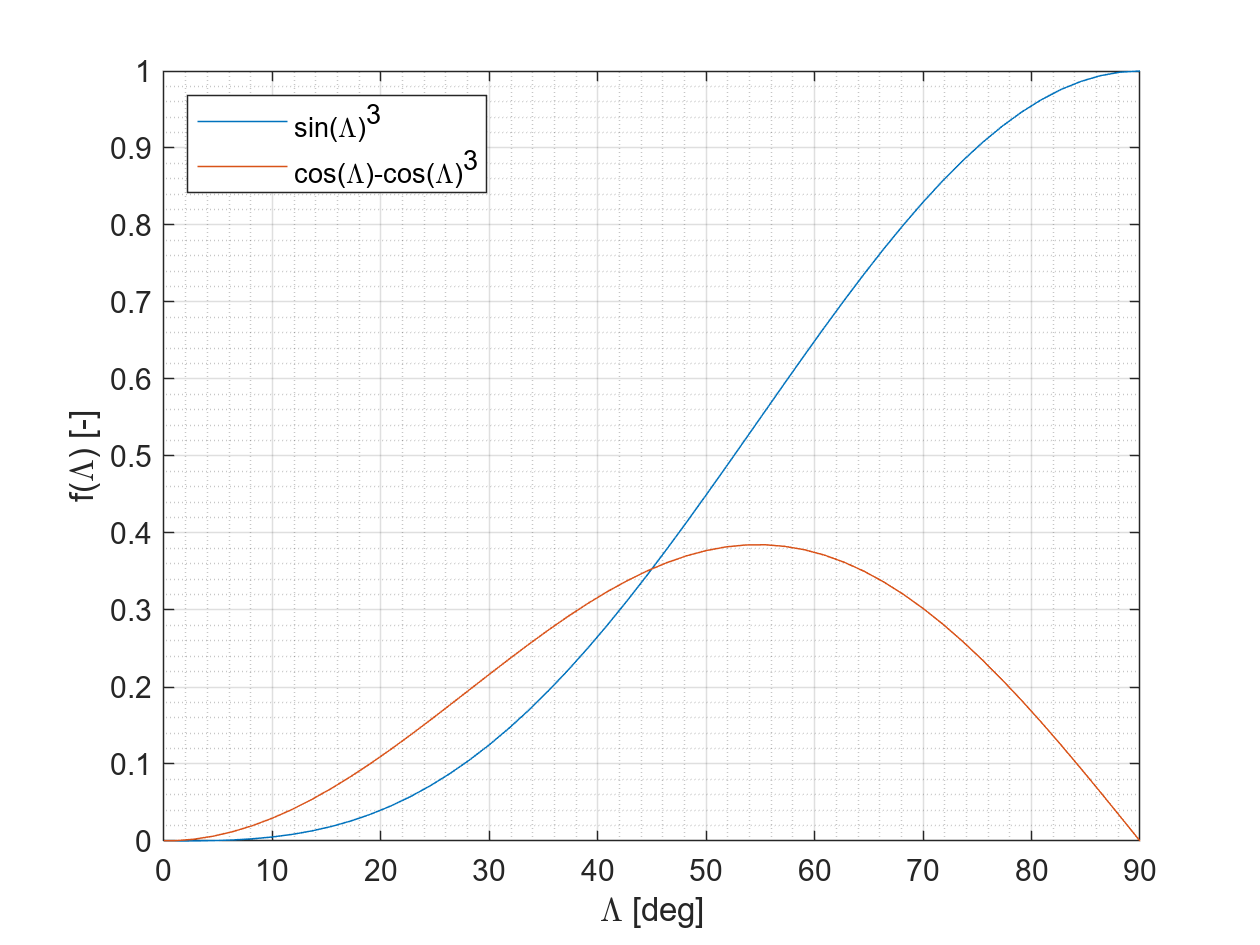

act_names = ["Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];
skew = [0,15,30,45,55,65];
folder = fullfile(pwd,'plots_save');
save_pictures = 1;
x = linspace(min(skew),max(skew));
order = 2;
s = "ZZZ_combined";
G1_q_90 = [G1_00(3,2),G1_00(1,2)];
axis = 1;
h = zeros(1,4);
f = figure(30);
clf 
cla
t = tiledlayout(1,2);
for j =1:2
    nexttile    
    for i = 1:4 
    data = [G1_00(i,:);G1_15(i,:);G1_30(i,:);G1_45(i,:);G1_55(i,:);G1_65(i,:)];
    data2 = [G2_00(i),G2_15(i),G2_30(i),G2_45(i),G2_55(i),G2_65(i)];

        switch i
            case {1,3}
                order = 1;
            case {2,4}
                if j==1
                    order = 12;%6
                else
                    order = 13;%5 3
                end
        end
        hold on 
        [rmse_log,p_out,h] =plot_special_v2(skew.',data(:,j),order,i,1,h);     
    end 
    switch j
        case 1
            ylim([-10.5,10.5])
            ylabel("Roll Effectiveness [rad s^{-2} pprz^{-1}]")
        case 2
            ylim([-5,5])
            ylabel("Pitch Effectiveness [rad s^{-2} pprz^{-1}]")
    end  
    xlim([0,60])
    xlabel("Skew [deg]")
    grid on
    grid minor
    hold off        
%     rmse_log      
end
% lgd = legend(h,["Roll Effectiveness","Pitch Effectiveness"],'NumColumns',2);
lgd = legend(h,act_names(1:4),'NumColumns',4);
lgd.Layout.Tile = 'north';  
f.Units = 'inches';
f.OuterPosition = [0 0 5.5 3];
if save_pictures
    exportgraphics(f,fullfile(folder,strcat(s,'.pdf')),'ContentType','vector')
end
s = "trigon";
x = linspace(-pi/2,pi/2);
figure(5)
clf
plot(rad2deg(x), sin(x).^3) 
hold on 
plot(rad2deg(x),cos(x)- cos(x).^3) 
grid on
grid minor
xlim([0,90])
ylim([0,1])
xlabel("\Lambda [deg]")
ylabel("f(\Lambda) [-]")
legend("sin(\Lambda)^3","cos(\Lambda)-cos(\Lambda)^3",'Location','northwest')

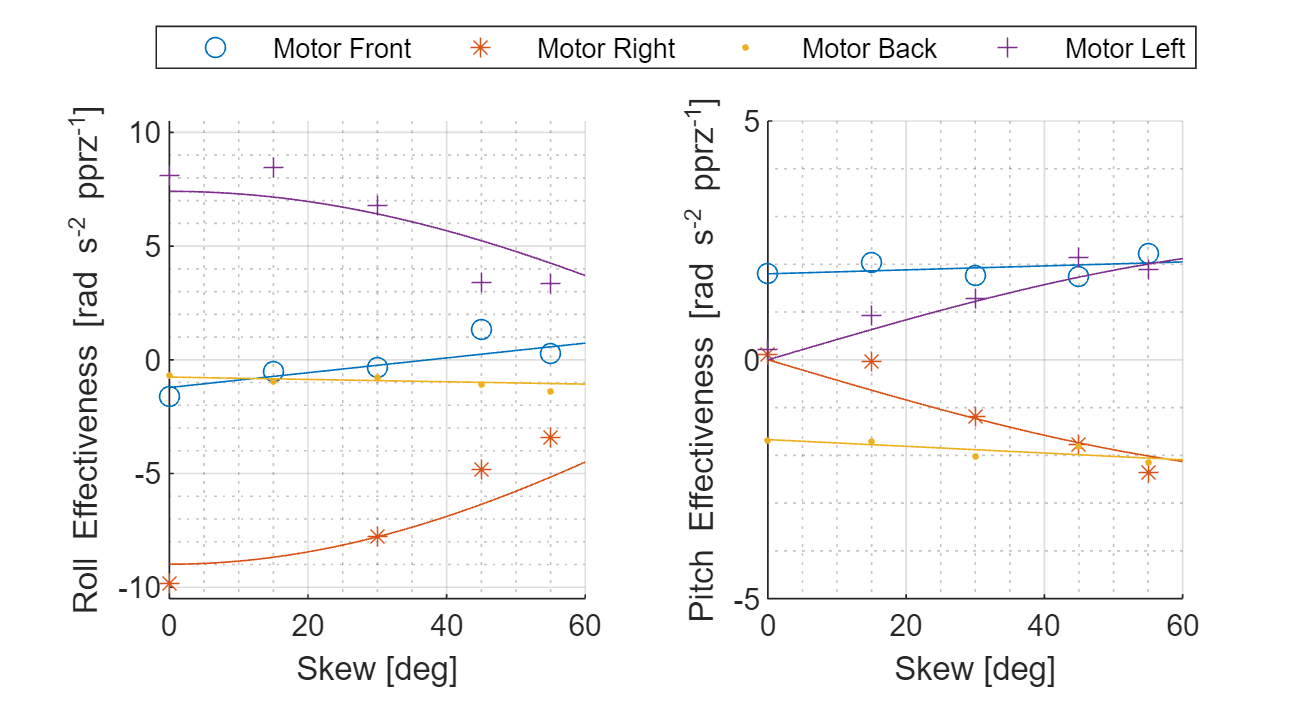

f.Units = 'inches';
f.OuterPosition = [0 0 5.5 3];
if save_pictures
    exportgraphics(f,fullfile(folder,strcat(s,'.pdf')),'ContentType','vector')
end